# Assignment 1 Experimental Data Processing

## The relationship between solar radio flux F10.7 and sunspot number.

#### Group 6:

- Andrei Shumeiko

- Ayush Gupta

- Olga Klyagina

- Simona Nitti

clc;
clear all;
close all;

### Task 1: Preparing the Data

#### Read the file 

load("data_group6");

Importing the monthly mean sunspot number and solar radio flux F10.7cm.

#### Data

year=data_group6(:,1);
month=data_group6(:,2);
flux=data_group6(:,3);
sunspot_number=data_group6(:,4);

Assigning the data into the given format.

#### Time

time=year+(month-1)./12;

### Task 2: Scatter plot between monthly mean sunspot number and solar radio flux F10.7cm

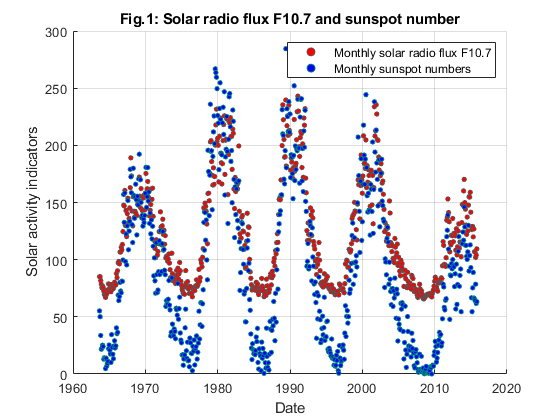

figure
hold on
scatter(time,flux,11, 'r', 'filled','MarkerEdgeColor',[.4 .3 .3])
scatter(time,sunspot_number,11, 'b','filled','MarkerEdgeColor',[0 .5 .5])

title('Fig.1: Solar radio flux F10.7 and sunspot number')
legend('Monthly solar radio flux F10.7','Monthly sunspot numbers')
ylabel('Solar activity indicators')
xlabel('Date')
grid on

This plot shows the monthly mean sunspot number and solar flux F10.7cm with noise. The maximum and minimum in the plot varies with the disturbances coming.

### Task 3: Smoothing the curve

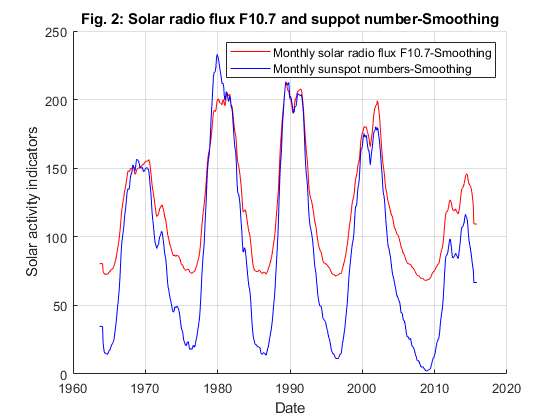

n = length(year);

sum_1 = 0;
sum_2 = 0;
sum_3 = 0;
sum_4 = 0;
for i = 1:6
    sum_1 = sum_1+flux(i);
    sum_2 = sum_2+sunspot_number(i);
    sum_3 = sum_3+flux(n-i+1);
    sum_4 = sum_4+sunspot_number(n-i+1);
end
R_flux(1:6) = sum_1/6;
R_sunspot(1:6) = sum_2/6;
R_flux(n-5:n) = sum_3/6;
R_sunspot(n-5:n) = sum_4/6;

 
for i = 7:(n-6)
    sum_1 = 0;
    sum_2 = 0;
    for j = i-5:i+5
        sum_1 = sum_1+flux(j);
        sum_2 = sum_2+sunspot_number(j);
    end
    R_flux(i) = sum_1/12 + (flux(i-6)+flux(i+6))/24;
    R_sunspot(i) = sum_2/12 + (sunspot_number(i-6)+sunspot_number(i+6))/24;
end

figure
hold on
plot(time,R_flux,'r')
plot(time,R_sunspot,'b')

title('Fig. 2: Solar radio flux F10.7 and suppot number-Smoothing')
legend('Monthly solar radio flux F10.7-Smoothing','Monthly sunspot numbers-Smoothing')
ylabel('Solar activity indicators')
xlabel('Date')
grid on

For better visualization and interpretition of the data 13-month running mean method is applied neglecting the noise.

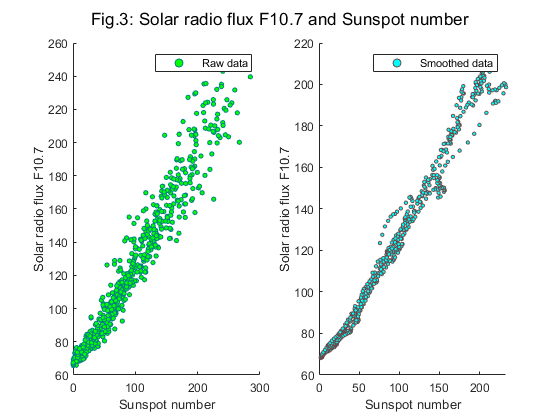

figure
subplot(1,2,1)
scatter(sunspot_number,flux,11,'g','filled','MarkerEdgeColor',[0 .5 .5])
ylabel('Solar radio flux F10.7')
xlabel('Sunspot number')
legend('Raw data')
subplot(1,2,2)
scatter(R_sunspot,R_flux,7, 'c', 'filled','MarkerEdgeColor',[.4 .3 .3])
ylabel('Solar radio flux F10.7')
xlabel('Sunspot number')
legend('Smoothed data')
sgtitle('Fig.3: Solar radio flux F10.7 and Sunspot number')

Fig 3. shows the correlation between the data for Solar flux F10.7 when the dataset was not smoothen and when the dataset was smoothen by 13-month running mean method for getting a more precise data.

### Task 4: Matrix of regressors vector

for i = 1:4
    R(:,i) = R_sunspot.^(i-1);
end

This is the matrix of independent variable regressors for finding the dependent variable regressand.

### Task 5: The vector of coefficients

[q,r] = qr(R);
beta= r\(r'\(R'*R_flux'))

beta =    67.2013
    0.3842
    0.0029
   -0.0000


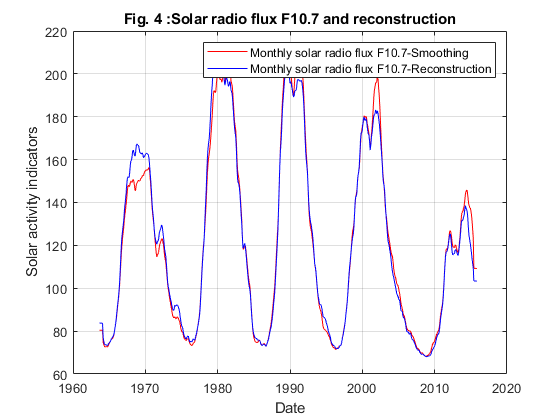

figure
F= R*beta;
plot(time,R_flux,'r',time,F,'b');
title('Fig. 4 :Solar radio flux F10.7 and reconstruction')
legend('Monthly solar radio flux F10.7-Smoothing','Monthly solar radio flux F10.7-Reconstruction')
ylabel('Solar activity indicators')
xlabel('Date')
grid on

The vector of coefficients is calculated, thus finding the dependent variable (F). The graph shows the goodness of the regression for the solar radio flux.

### Task 6: Variance of estimation error of solar radio flux at 10.7

sum=0;
for i=1:n
    sum=sum+(R_flux(i)-F(i))^2;
end

variance=sum/(n-1)

variance = 29.0928

standard_deviation=variance^(1/2)

standard_deviation = 5.3938

The variance and standard deviation of the regression is calculated and compared with the flux value for each year.

### Task 7: Conclusions

- After downloading the data the scatter plot shows the solar activity from the year 1963 to 2015 with noise having very sharp maximas and minimas.

- The raw data is hard to analyze as peaks positions are uncertain, so are amplitudes. 13-month running mean method helps to identify these values more properly and smoothen the data precisely. By smoothening the curves of the solar flux it helps in interpreting the data more accurately and dimish the random noise.

- The processed data tells goodness of regression in the solar radio flux with a standard deviation of 5.3938. The close proximity of both the curves thus can help in better future predictions of the model.